# [Solution] Time-dependent DMRG (tDMRG): Error analysis

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Complete the function for tDMRG

The complete version of the function, `tDMRG.m`, is added under the `DMRG` directory. Compare with your version!

## Solution to Exercise (b): Change `Nkeep` and `dt`

Let's compare the error of the tDMRG result against the exact solution, for different values of `Nkeep` and `dt`.

clear

% system parameter
J = -1; % coupling strength
L = 50; % number of sites in a chain

% DMRG parameter
Nkeep = [10 20 30]; % bond dimension
dt = [1/40 1/20 1/10]; % discrete time step size
tmax = 20; % maximum time

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% nearest-neighbor interaction terms
Hs = cell(1,L-1);
Hs(:) = {J*contract(S(:,:,[1 3]),3,3, ...
    permute(conj(S(:,:,[1 3])),[2 1 3]),3,3)};

% operator to measure magnetization
Sz = S(:,:,2);

% initialize MPS: product state such that the left half of the chain is
% up-polarized and the right half is down-polarized.
M = cell(1,L);
for itN = (1:L)
    if itN <= (L/2)
        M{itN} = permute([1,0],[1 3 2]);
    else
        M{itN} = permute([0,1],[1 3 2]);
    end
end

% result
ts = cell(numel(Nkeep),numel(dt));
Ovals = cell(size(ts));
EE = cell(size(ts));
dw = cell(size(ts));

% tDMRG
for itN = (1:numel(Nkeep))
    for itt = (1:numel(dt))
        [ts{itN,itt},~,Ovals{itN,itt},EE{itN,itt},dw{itN,itt}] = ...
            tDMRG(M,Hs,Sz,Nkeep(itN),dt(itt),tmax);
    end
end

tDMRG : Real-time evolution with local measurements
N = 50, Nkeep = 10, dt = 0.025, tmax = 20 (800 steps)
22-10-08 21:44:48 | Transform the MPS into right-canonical form.
22-10-08 21:44:48 | Trotter steps: start
22-10-08 21:44:51 | #80/800 : t = 2/20
22-10-08 21:44:53 | #160/800 : t = 4/20
22-10-08 21:44:56 | #240/800 : t = 6/20
22-10-08 21:44:59 | #320/800 : t = 8/20
22-10-08 21:45:02 | #400/800 : t = 10/20
22-10-08 21:45:05 | #480/800 : t = 12/20
22-10-08 21:45:08 | #560/800 : t = 14/20
22-10-08 21:45:11 | #640/800 : t = 16/20
22-10-08 21:45:15 | #720/800 : t = 18/20
22-10-08 21:45:18 | #800/800 : t = 20/20
Elapsed time: 29.94s, CPU time: 39.47s, Avg # of cores: 1.318
22-10-08 21:45:18 | Memory usage : 3.26GiB
tDMRG : Real-time evolution with local measurements
N = 50, Nkeep = 10, dt = 0.05, tmax = 20 (400 steps)
22-10-08 21:45:18 | Transform the MPS into right-canonical form.
22-10-08 21:45:18 | Trotter steps: start
22-10-08 21:45:19 | #40/400 : t = 2/20
22-10-08 21:45:20 | #80/400 

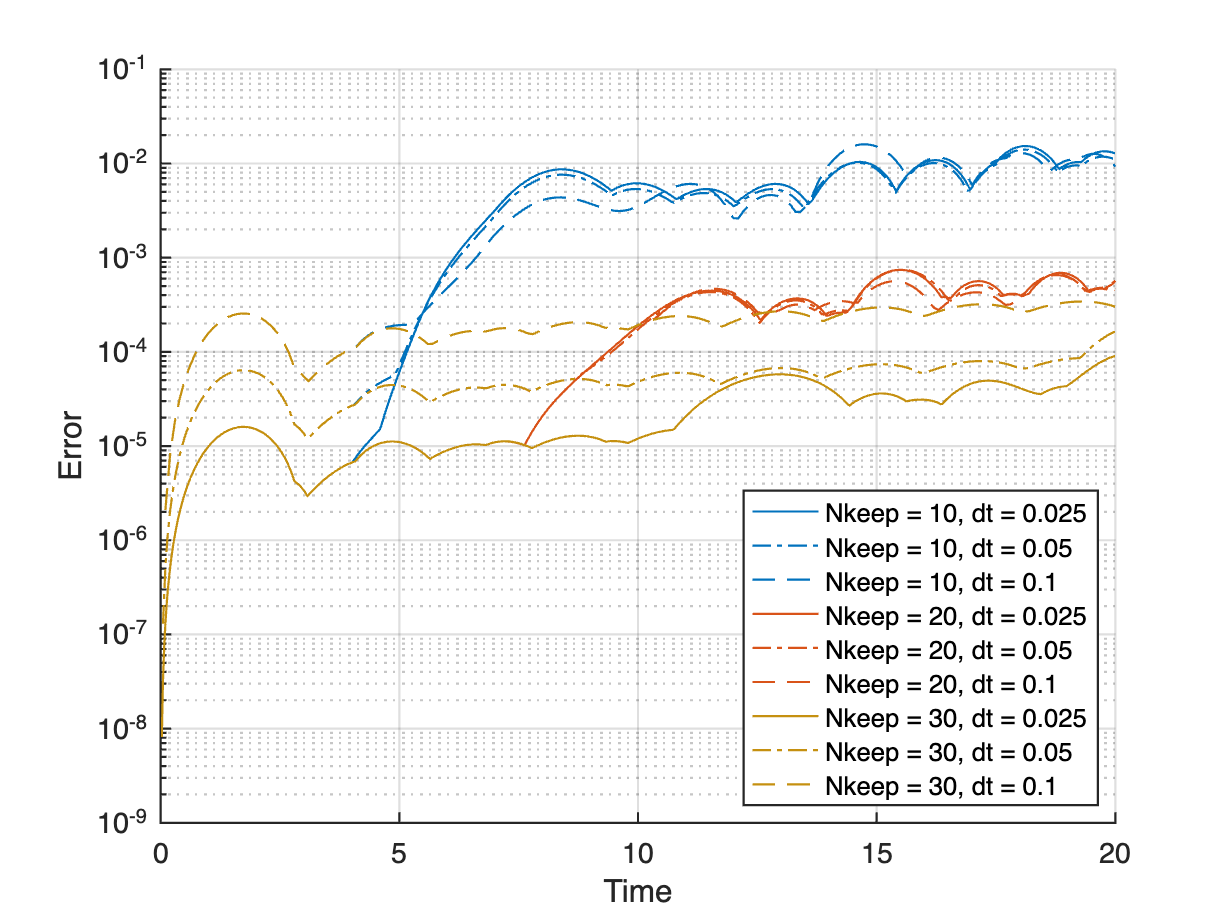

Oexact = cell(1,numel(dt)); % exact result, for different time grids

for itt = (1:numel(dt))
    fvals = zeros(numel(ts{1,itt}),L-1);
    for it = (1:size(fvals,2))
        fvals(:,it) = (besselj(it-(L/2),ts{1,itt}(:))).^2;
    end
    fvals = -0.5*fvals;
    
    Oexact{itt} = zeros(numel(ts{1,itt}),L/2);
    for it = (1:(L/2))
        Oexact{itt}(:,it) = sum(fvals(:,(L/2-it+1):(it+L/2-1)),2);
    end
    Oexact{itt} = [-fliplr(Oexact{itt}),Oexact{itt}];
end

% color to distinguish Nkeep
clrs = [0 .447 .741; .85 .325 .098; .773 .565 .061];
% line style to distinguish dt
lnst = {'-','-.','--'};

figure;
legs = cell(size(ts));
hold on;
for itN = (1:numel(Nkeep))
    for itt = (1:numel(dt))
        plot(ts{itN,itt},max(abs(Ovals{itN,itt}-Oexact{1,itt}),[],2), ...
            'LineWidth',1,'Color',clrs(itN,:),'LineStyle',lnst{itt});
        legs{itN,itt} = ['Nkeep = ',sprintf('%i',Nkeep(itN)), ...
            ', dt = ',sprintf('%.4g',dt(itt))];
    end
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
grid on;
xlabel('Time');
ylabel('Error');
legs = legs.'; % to match with the order of lines
legend(legs(:),'Location','southeast');

For smaller values of `Nkeep` = 10 and 20, there appear "runaway" times after which the error increases rapidly. This error is governed by the **truncation error**: small bond dimensions cannot fully capture the entanglement growth. So for smaller `Nkeep`, runaway time comes earlier, since it more suffers with the truncation error.

On the other hand, for larger value of `Nkeep` = 30, there is no runaway time visible within this time interval. Instead, the result for smaller time step size `dt` has a lower error. That is, the error for `Nkeep` = 30 is governed by the **Trotterization error** that arises from discretizing the continuous time evolution operator $\exp (-i \hat{H}_\mathrm{XY} t)$ into several Trotter steps.

To focus on the truncation error, we plot the discarded weight. Here we sum over the discarded weights over the chain for every three Trotter steps, i.e., the time evolution over a time step `dt`.

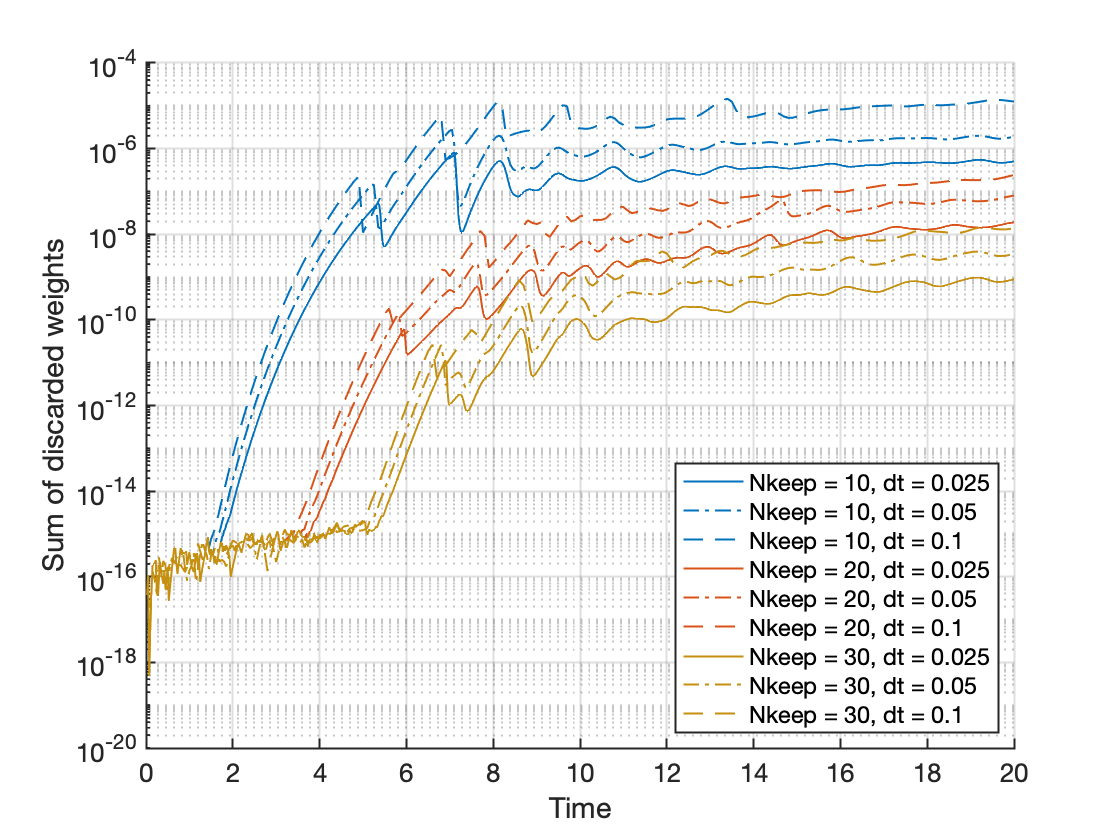

figure;
legs = cell(size(ts));
hold on;
for itN = (1:numel(Nkeep))
    for itt = (1:numel(dt))
% sum over discarded weights along the chain, for three Trotter steps
        plot(ts{itN,itt}, ...
            sum(sum(reshape(dw{itN,itt}, ...
            [3, size(dw{itN,itt},1)/3, size(dw{itN,itt},2)]),1),3), ...
            'LineWidth',1,'Color',clrs(itN,:),'LineStyle',lnst{itt});
        legs{itN,itt} = ['Nkeep = ',sprintf('%i',Nkeep(itN)), ...
            ', dt = ',sprintf('%.4g',dt(itt))];
    end
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
grid on;
xlabel('Time');
ylabel('Sum of discarded weights');
legs = legs.'; % to match with the order of lines
legend(legs(:),'Location','southeast');

The jumps of the discarded weights indicate that the bond truncations start to lose the information of the system. For larger `Nkeep`, the discarded weight remains small for longer period of time.

## Solution to Exercise (c): Longer time evolution

Let's run the tDMRG calculation for longer time, `tmax = 80`.

clear

% system parameter
J = -1; % coupling strength
L = 50; % number of sites in a chain

% DMRG parameter
Nkeep = 20; % bond dimension
dt = 1/20; % discrete time step size
tmax = 80; % maximum time

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% nearest-neighbor interaction terms
Hs = cell(1,L-1);
Hs(:) = {J*contract(S(:,:,[1 3]),3,3, ...
    permute(conj(S(:,:,[1 3])),[2 1 3]),3,3)};

% operator to measure magnetization
Sz = squeeze(S(:,:,2));

% initialize MPS: product state such that the left half of the chain is
% up-polarized and the right half is down-polarized.
M = cell(1,L);
for itN = (1:L)
    if itN <= (L/2)
        M{itN} = permute([1,0],[1 3 2]);
    else
        M{itN} = permute([0,1],[1 3 2]);
    end
end

% tDMRG
[ts,M,Ovals,EE,dw] = tDMRG(M,Hs,Sz,Nkeep,dt,tmax);

tDMRG : Real-time evolution with local measurements
N = 50, Nkeep = 20, dt = 0.05, tmax = 80 (1600 steps)
22-10-08 21:49:28 | Transform the MPS into right-canonical form.
22-10-08 21:49:28 | Trotter steps: start
22-10-08 21:49:34 | #160/1600 : t = 8/80
22-10-08 21:49:44 | #320/1600 : t = 16/80
22-10-08 21:49:55 | #480/1600 : t = 24/80
22-10-08 21:50:09 | #640/1600 : t = 32/80
22-10-08 21:50:22 | #800/1600 : t = 40/80
22-10-08 21:50:35 | #960/1600 : t = 48/80
22-10-08 21:50:49 | #1120/1600 : t = 56/80
22-10-08 21:51:03 | #1280/1600 : t = 64/80
22-10-08 21:51:16 | #1440/1600 : t = 72/80
22-10-08 21:51:29 | #1600/1600 : t = 80/80
Elapsed time: 121.4s, CPU time: 761.8s, Avg # of cores: 6.273
22-10-08 21:51:29 | Memory usage : 3.34GiB


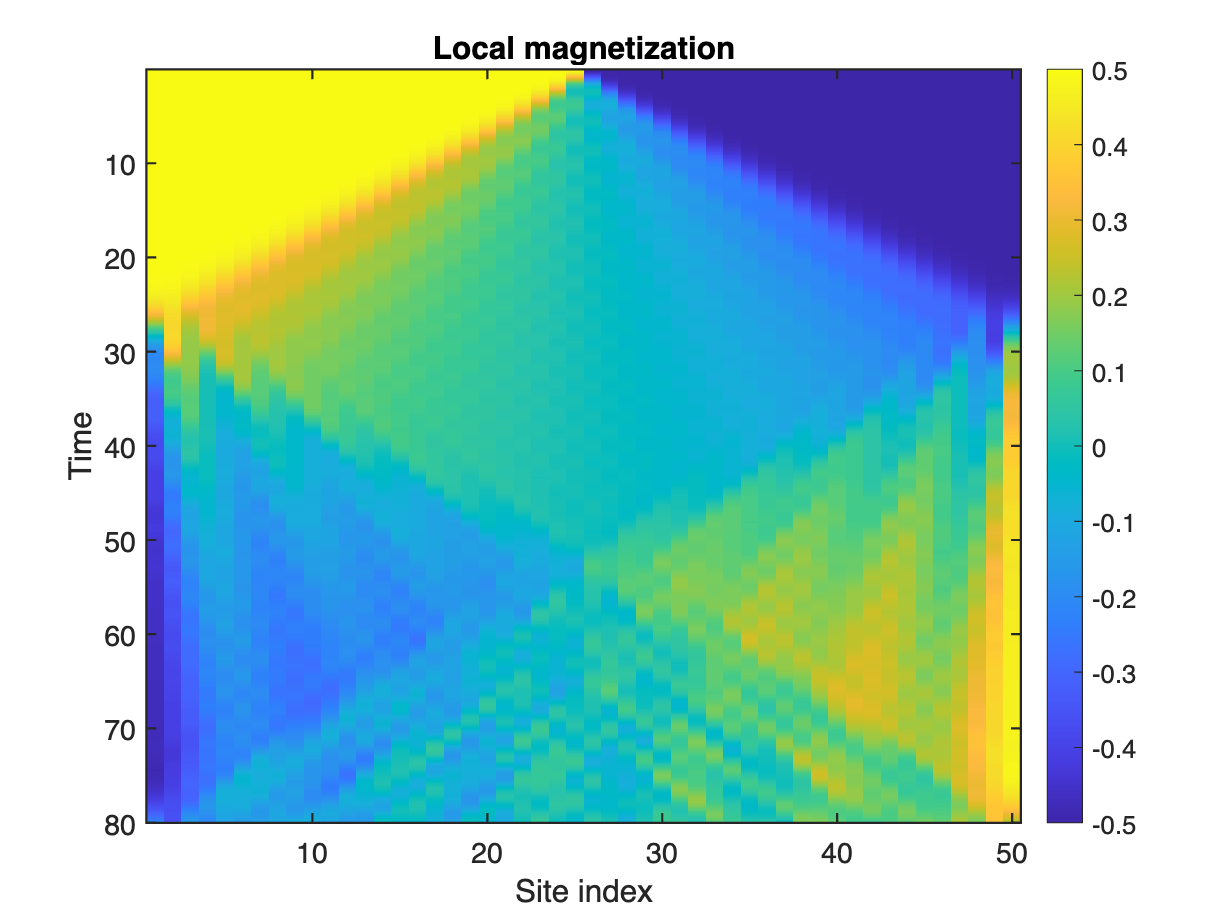

Ovals = real(Ovals); % remove noise
figure;
imagesc([1 L],[ts(1) ts(end)],real(Ovals));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Local magnetization');

We see that the wavefronts of magnetization fluctuation bounce back from the ends of the system and then manifest interference-like pattern. Since the analytic solution which uses the Bessel functions covers **before** the wavefronts reache the ends of the system, we cannot make an error analysis based on the exact result.

Instead, we can use the discarded weight as the measure of the truncation error.

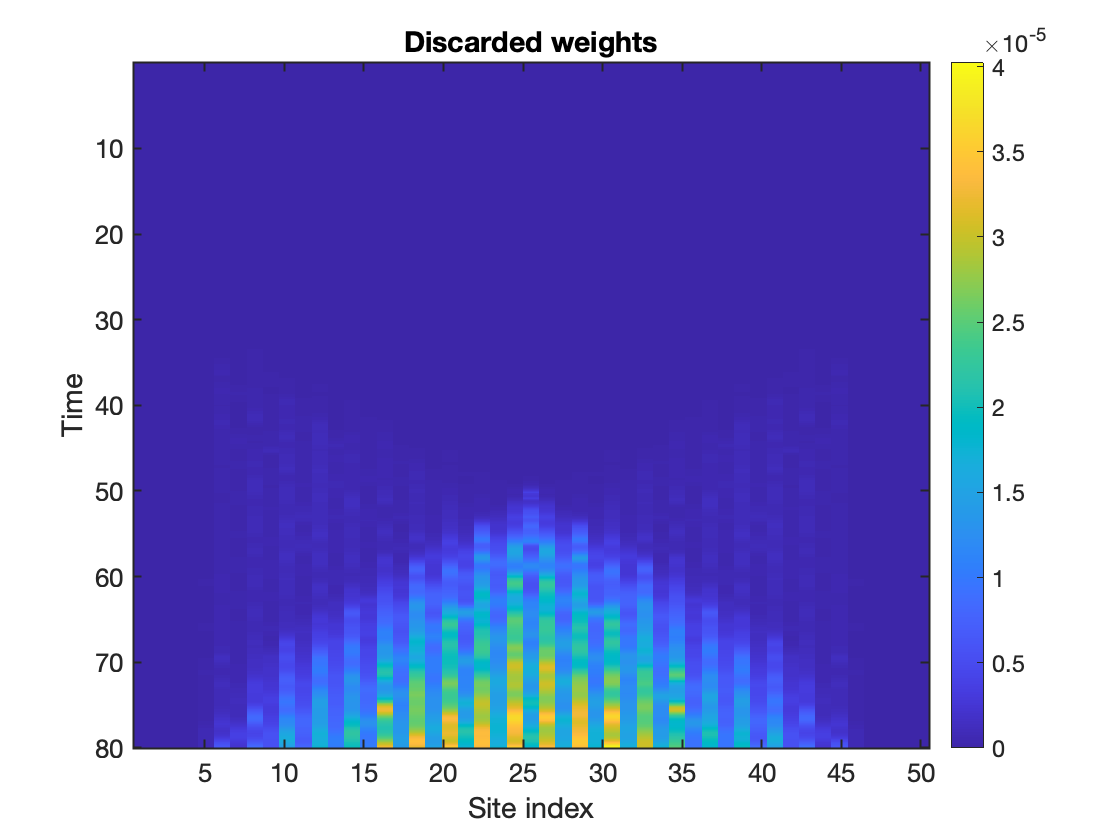

figure;
imagesc([1 L],[ts(1) ts(end)], ...
    squeeze(sum(reshape(dw,[3, size(dw,1)/3, size(dw,2)]))));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Discarded weights');

Keep in mind that there is another source of error: the Trotter error. The discarded weights cannot capture the Trotter error.

The discarded weight is larger for bonds and at time steps where the entaglement is large.

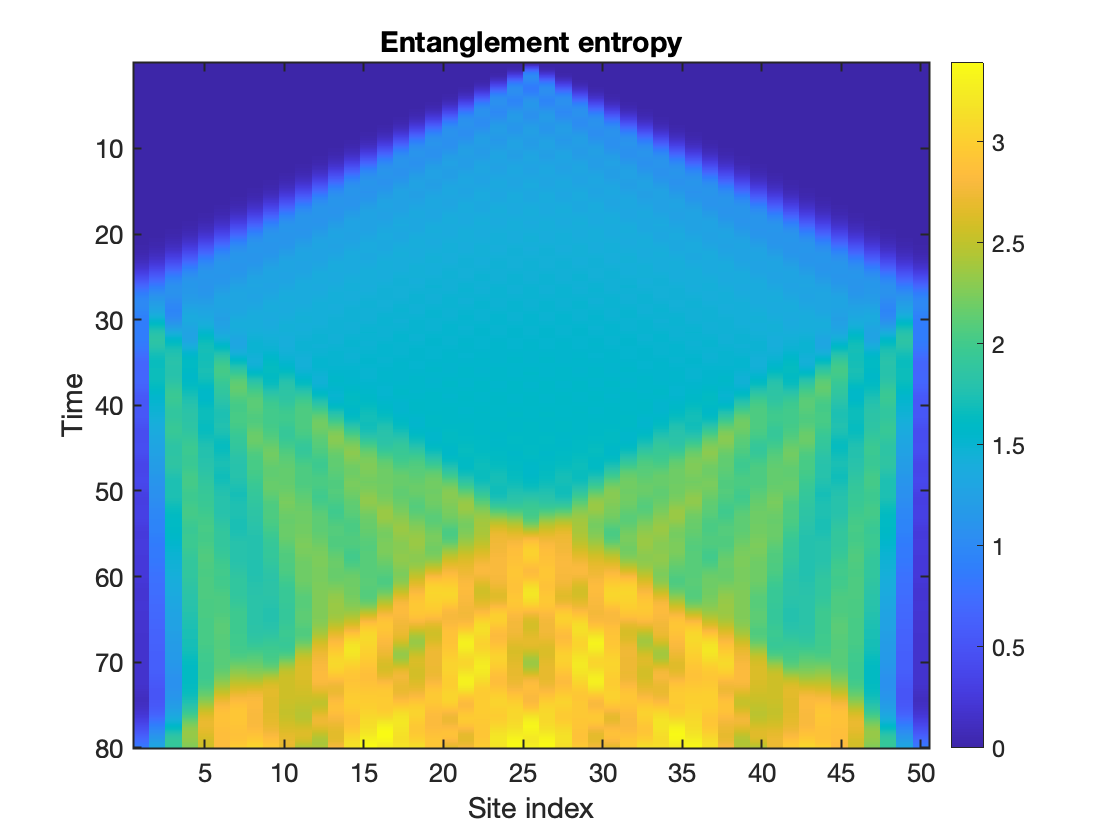

figure;
imagesc([1 L],[ts(1) ts(end)],EE(3:3:end,:));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Entanglement entropy');

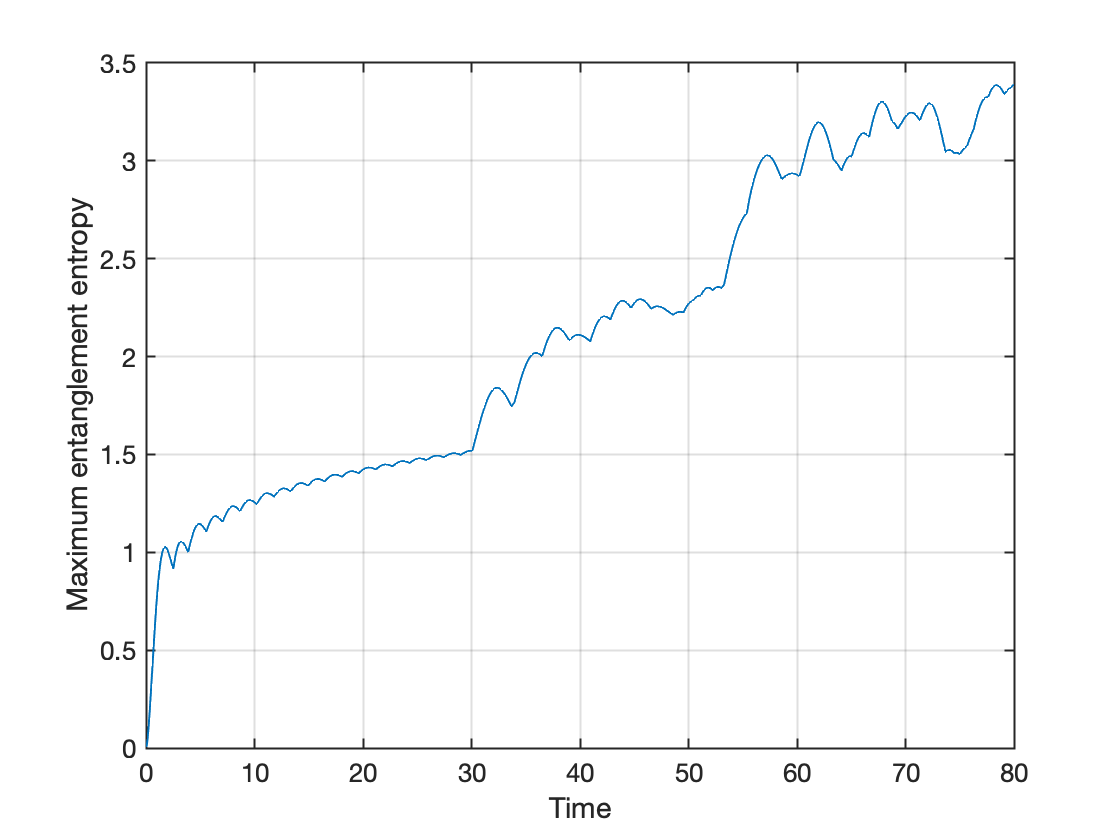


% maximum entanglement entropy along the chain, at each time step
figure;
plot(ts,max(EE(3:3:end,:),[],2),'LineWidth',1);
hold off
set(gca,'FontSize',13,'LineWidth',1);
ylabel('Maximum entanglement entropy');
xlabel('Time');
grid on;

At later time steps, the entanglement entropy (roughly speaking) lineary grows with time. Such growth of the entanglement and the discarded weights indicates the necessity of larger bond dimensions, for better simulating the time evolution.

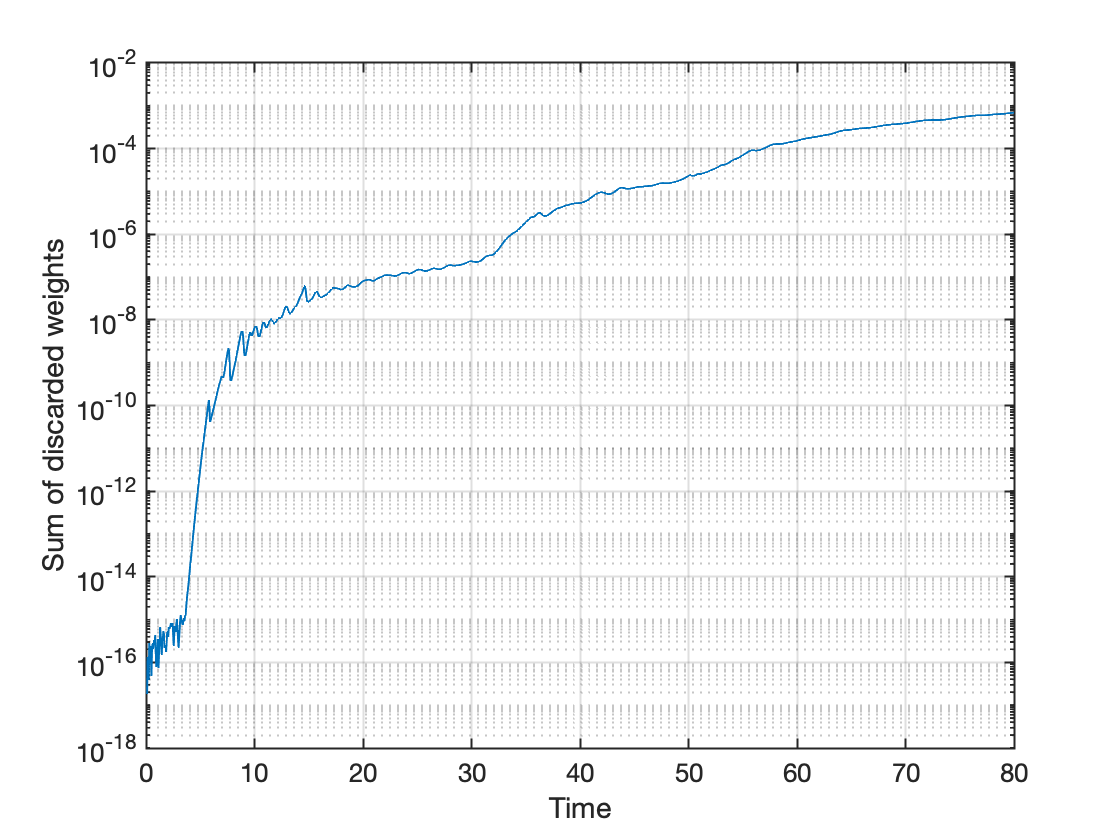

figure;
plot(ts,sum(sum(reshape(dw,[3, size(dw,1)/3, size(dw,2)]),1),3), ...
    'LineWidth',1);
% sum over every three Trotter steps, to match with time grid
set(gca,'FontSize',13,'LineWidth',1,'YScale','log');
ylabel('Sum of discarded weights');
xlabel('Time');
grid on;

## Solution to Exercise (d): Different initial state where only one spin is up

Prepare the initial state $|\Psi(t=0)\rangle = \hat{S}_{n,+} |\!{\downarrow},\ldots,{\downarrow}\rangle ,$ where $n = 10$.

clear

% system parameter
J = +1; % coupling strength
L = 50; % number of sites in a chain
n = 10; % location of up spin at t = 0

% DMRG parameter
Nkeep = 20; % bond dimension
dt = 1/20; % discrete time step size
tmax = 80; % maximum time

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% nearest-neighbor interaction terms
Hs = cell(1,L-1);
Hs(:) = {J*contract(S(:,:,[1 3]),3,3, ...
    permute(conj(S(:,:,[1 3])),[2 1 3]),3,3)};

% operator to measure magnetization
Sz = squeeze(S(:,:,2));

% initialize MPS: product state such that the left half of the chain is
% up-polarized and the right half is down-polarized.
M = cell(1,L);
M(:) = {permute([0,1],[1 3 2])}; % spin down
M{n} = permute([1,0],[1 3 2]); % spin up

% tDMRG
[ts,M,Ovals,EE,dw] = tDMRG(M,Hs,Sz,Nkeep,dt,tmax);

tDMRG : Real-time evolution with local measurements
N = 50, Nkeep = 20, dt = 0.05, tmax = 80 (1600 steps)
22-10-08 21:57:58 | Transform the MPS into right-canonical form.
22-10-08 21:57:58 | Trotter steps: start
22-10-08 21:58:04 | #160/1600 : t = 8/80
22-10-08 21:58:09 | #320/1600 : t = 16/80
22-10-08 21:58:14 | #480/1600 : t = 24/80
22-10-08 21:58:19 | #640/1600 : t = 32/80
22-10-08 21:58:24 | #800/1600 : t = 40/80
22-10-08 21:58:29 | #960/1600 : t = 48/80
22-10-08 21:58:34 | #1120/1600 : t = 56/80
22-10-08 21:58:39 | #1280/1600 : t = 64/80
22-10-08 21:58:44 | #1440/1600 : t = 72/80
22-10-08 21:58:49 | #1600/1600 : t = 80/80
Elapsed time: 50.5s, CPU time: 54.23s, Avg # of cores: 1.074
22-10-08 21:58:49 | Memory usage : 3.43GiB


Similary to the previous case of the "half-half" magnetized initial state, the magnetization fluctuation propagates from the site $n$ and then reflected from boundaries.

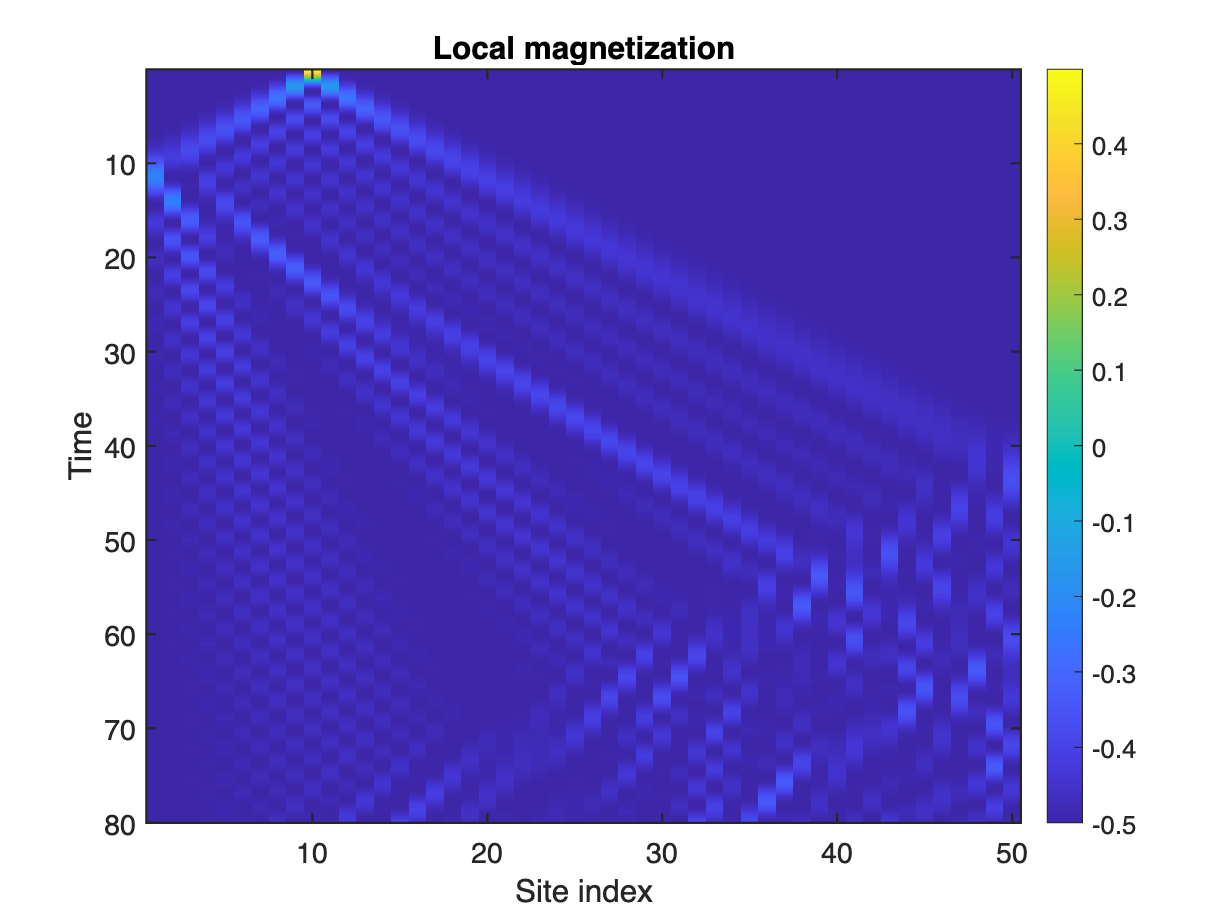

Ovals = real(Ovals); % remove noise
figure;
imagesc([1 L],[ts(1) ts(end)],real(Ovals));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Local magnetization');

Compute the error of the tDMRG result against the exact solution. Note that in this case the exact result can also describes the "reflection" of magnetization fluctuation.

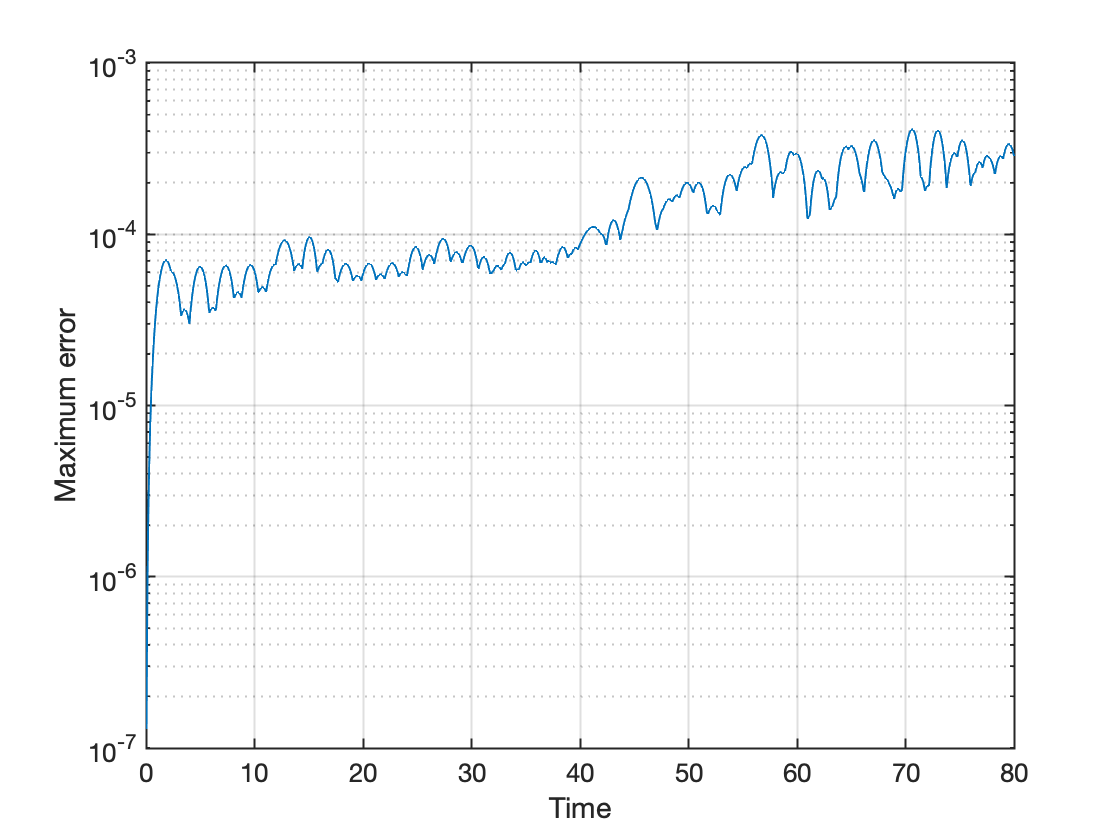

Oexact = zeros(numel(ts),L);
for itt = (1:numel(ts))
    for itN = (1:L)
        Oexact(itt,itN) = -0.5+abs(sum((2/(L+1))*sin(pi*(1:L)*n/(L+1)).* ...
            sin(pi*(1:L)*itN/(L+1)).*exp(-1i*ts(itt)*cos(pi*(1:L)/(L+1))))).^2;
    end
end

% error between numerical and exact results
figure;
% maximum error along the chain at each time instance
plot(ts,max(abs(Ovals-Oexact),[],2),'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1,'YScale','log');
grid on;
xlabel('Time');
ylabel('Maximum error');

The error growth is much slower than the error in the cases discussed so far. Why is the error small? We can figure it out from the entanglement entropy and the discarded weights.

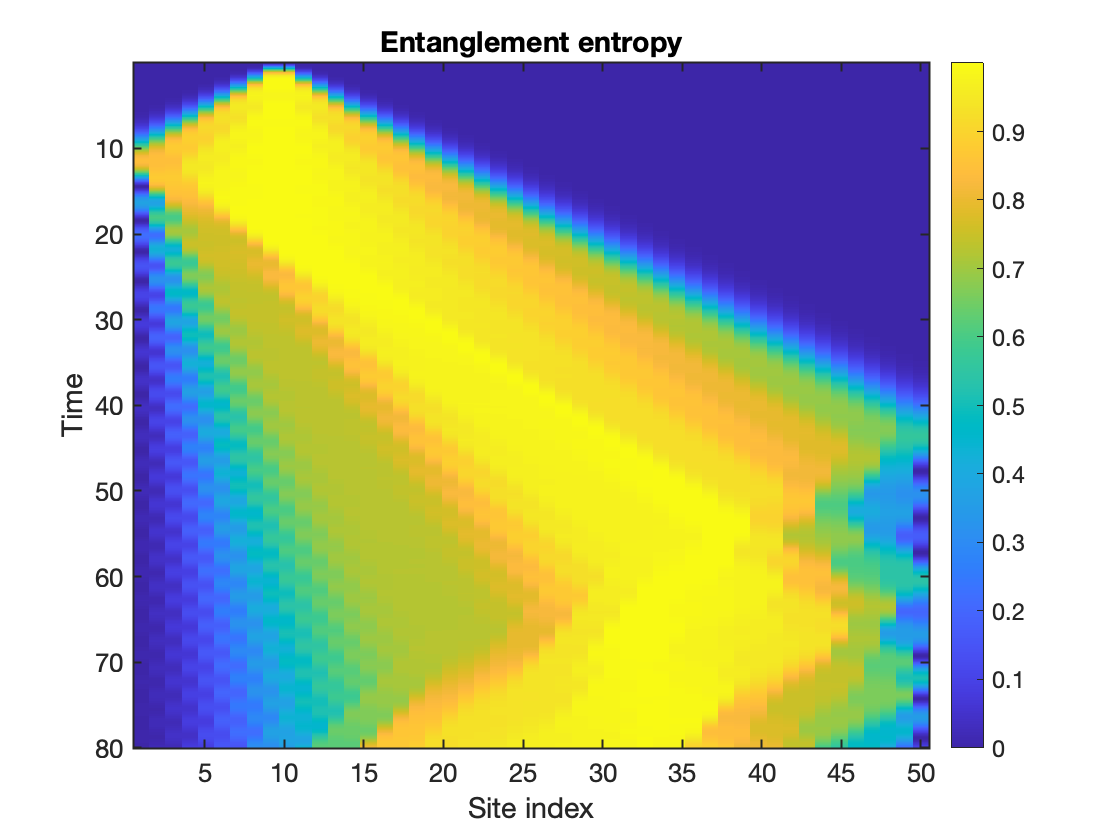

figure;
imagesc([1 L],[ts(1) ts(end)],EE(3:3:end,:));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Entanglement entropy');

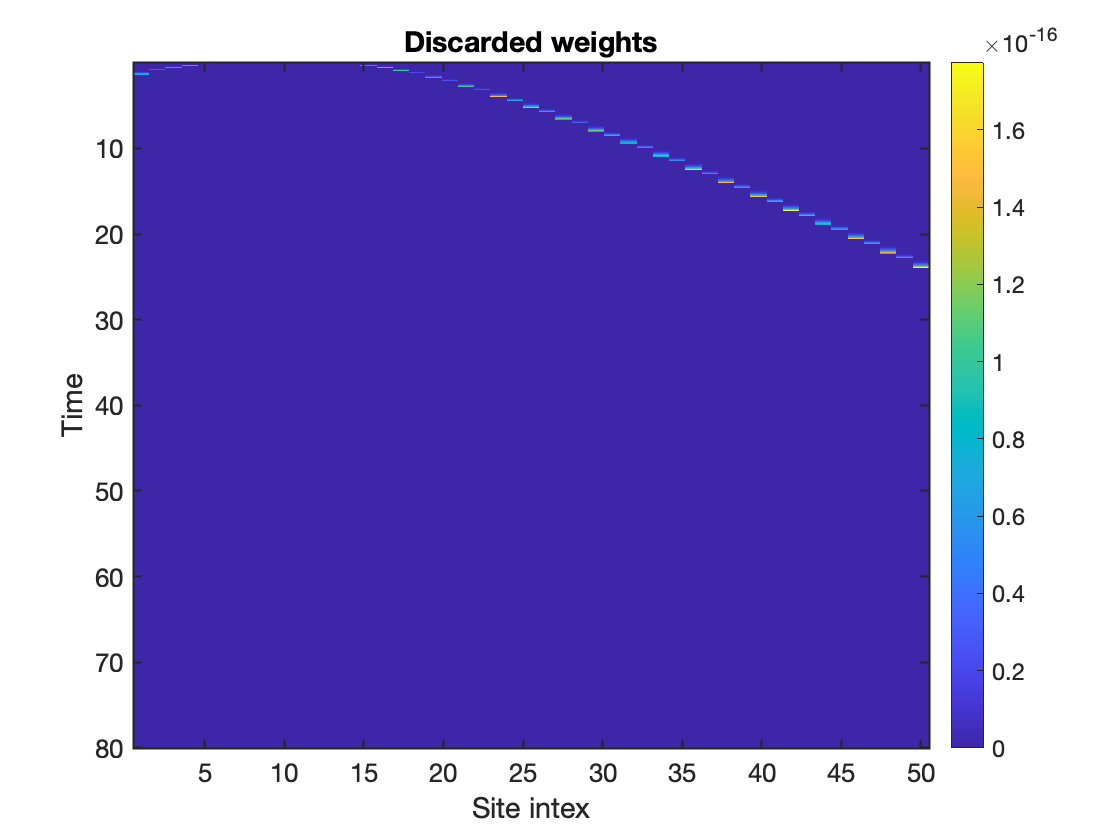

figure;
imagesc([1 L],[ts(1) ts(end)], ...
    squeeze(sum(reshape(dw,[3, size(dw,1)/3, size(dw,2)]),1)));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site intex');
ylabel('Time');
title('Discarded weights');

In this case of the "only one up" initial state, the maximum entanglement entropy at each time instance is upper bounded by 1. And there are **no** discarded singular values, up to double precision!

It is because the effective Hilbert space for this time evolution is small. The total spin-$z$ quantum number of the initlal state $S_z = 1 - L/2$ is conserved along the time evolution, since the Hamiltonian respects the conservation of $S_z$. Indeed, there are only $L$ orthogonal states with $S_z = 1- L/2$. So the tDMRG calculation of such case does not suffer the entanglement growth.

Therefore, the error in this example is solely due to the Trotterization error.